3clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
OD_circle_image_path = fullfile('OD_circle_SQ_9_images');
load('meanHistRGB9.mat');%esto te da la variable MeanHistRGB
vignette=double(rgb2gray(imread('viñeta2.jpg')));
vignette=vignette./max(vignette(:));

factor_reduccion = 1/10; 
dimensiones_nuevas = [2425, 3005];%Para que todas las imagenes entren al for con el mismo tamaño
margen=300/10;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas

tR=0.5;
tG=2;
tB=1;


Hago la matriz del círculo:

margen_zoom=430;
se = strel('disk',100);

indices = find(T.quality == 4);

n = (2*margen_zoom)+1;
[x, y] = meshgrid(-n/2:n/2-1, -n/2:n/2-1);
distancia = sqrt(x.^2 + y.^2);
radio = n/2;
circulo = distancia <= radio;
circulo=double(circulo);

for u = 1:length(indices)
    k=indices(u);
    % Leer la imagen original

k = 9

RGB = imread(string(fullfile(img_path, T{k,1})));%Voy a buscar el OD de esta imagen
RGB(:,:,1)=medfilt2(RGB(:,:,1),[3 3],"symmetric");
RGB(:,:,2)=medfilt2(RGB(:,:,2),[3 3],"symmetric");
RGB(:,:,3)=medfilt2(RGB(:,:,3),[3 3],"symmetric");

[media_izquierda,media_derecha]=medias(RGB,se);

if (media_derecha > 100) || (media_izquierda > 100)%si detecta que esta quemado (media>100) ejecuta el código)
       [RGB_sinQuemado]=oscurecerQuemados(RGB, vignette);

    [media_izquierda,media_derecha]=medias(RGB_sinQuemado,se);
    if (media_derecha > 100) || (media_izquierda > 100)
        [RGB_sinQuemado]=oscurecerQuemados(RGB_sinQuemado, vignette);
    end

else
    RGB_sinQuemado=uint8(RGB);
end

RGB=uint8(RGB);

%Aquí en vez de hacer dos cambios se podría poner uno y ya, hay que
%mirarlo...
[alto_original, ancho_original, ~] = size(RGB_sinQuemado);
imagen_redimensionada = imresize(RGB_sinQuemado, dimensiones_nuevas);
new_size = [size(imagen_redimensionada, 1) * factor_reduccion, size(imagen_redimensionada, 2) * factor_reduccion];
RGBa = imresize(imagen_redimensionada, new_size, 'bicubic');

[alto, ancho, ~] = size(RGBa);
CM=zeros(alto-margen*2,ancho-margen*2);
diff=zeros(alto-margen*2,ancho-margen*2);
dif=zeros(alto-margen*2,ancho-margen*2,3);

for i=1:3
    for x=margen+1:ancho-margen
        for y=margen+1:alto-margen
            layer_zoom=RGBa(y-margen:y+margen, x-margen:x+margen, i);
            [hist_layer, ~] = imhist(layer_zoom);
            diff(y-margen,x-margen)=sum(bsxfun(@minus, hist_layer, meanHistRGB(i)).^2);
        end
        
    end
    dif(:,:,i)=diff;
end

c=1/(1+dif);
CM = c(:,:,1).*tR + c(:,:,2).*tG + c(:,:,3);
CM_padded = padarray(CM, [margen margen], 0);%como no se ha puesto un margen, ahora hay que hacerle un padding pa sumárselo
CM_padded_redimensioned = imresize(CM_padded, [alto_original ancho_original]);
thres=CM_padded_redimensioned>0.93*max(CM_padded_redimensioned(:));

Utilizando en vez del máximo, el 0,98 máximo y calculando el centroide

[row, col] = find(thres);%Busca los elementos no 0
centroideX = round(mean(col)); %lo redondeo porque lo que quiero es la posición de un pixel, tiene que ser integer
centroideY = round(mean(row));

Ahora voy a conseguir un circulo con el OD dentro

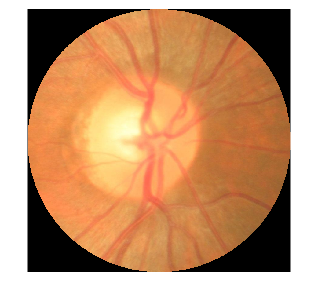

stats = 250×6 table
     Centroid     MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Circularity
    __________    _______________    _______________    ____________    ___________    ___________

    NaN    NaN           0                  0                0               0              1     
    NaN    NaN           0                  0                0               0              1     
    NaN    NaN           0                  0                0               0              1     
    NaN    NaN           0                  0                0               0              1     
    NaN    NaN           0                  0                0               0              1     
    NaN    NaN           0                  0                0               0    

stats = 43×6 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Circularity
    ________________    _______________    _______________    ____________    ___________    ___________

    309.91    412.57        992.34              711.8           0.69677          78.571           1     
    280.32    412.15        943.47             719.52           0.64684          81.238           1     
    255.12    422.21         904.6             709.43           0.62044          84.432           1     
    237.18    420.35        861.12             699.62           0.58302          86.945           1     
    230.39    416.96        842.93             671.11           0.60507         -89.039           1     
    224.36    410.94        836.05       

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


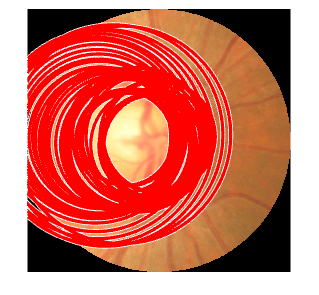

if centroideY+margen_zoom>height(RGB)
   centroideY=height(RGB)-margen_zoom;
elseif centroideY-margen_zoom<1
    centroideY=margen_zoom+1;
end

if centroideX+margen_zoom>width(RGB)
   centroideX=width(RGB)-margen_zoom;
elseif centroideX-margen_zoom<1
    centroideX=margen_zoom+1;
end

OD_zoomR=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,1);
OD_zoomG=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,2);
OD_zoomB=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,3);

OD_zoomR=double(OD_zoomR);
OD_zoomG=double(OD_zoomG);
OD_zoomB=double(OD_zoomB);

OD_circleR=OD_zoomR.*circulo;
OD_circleG=OD_zoomG.*circulo;
OD_circleB=OD_zoomB.*circulo;
OD_circleRGB = cat(3, OD_circleR, OD_circleG, OD_circleB);%Para juntar las 3 layers

OD_circleRGB=uint8(OD_circleRGB);

% Guardar la imagen modificada en el directorio correspondiente
nombre_archivo = cell2mat(fullfile(OD_circle_image_path, T{k,1})); 
imwrite(OD_circleRGB, nombre_archivo);
end
